Lektion 3 - Robot perception

Setup:

rosshutdown

Shutting down global node /matlab_global_node_52778 with NodeURI http://192.168.7.12:58967/


setenv('ROS_MASTER_URI','http://192.168.7.34:11311')
setenv('ROS_IP','192.168.7.12')
rosinit('http://192.168.7.34:11311','NodeHost','192.168.7.12');

Initializing global node /matlab_global_node_32644 with NodeURI http://192.168.7.12:59011/


Opgave 1 - Image input

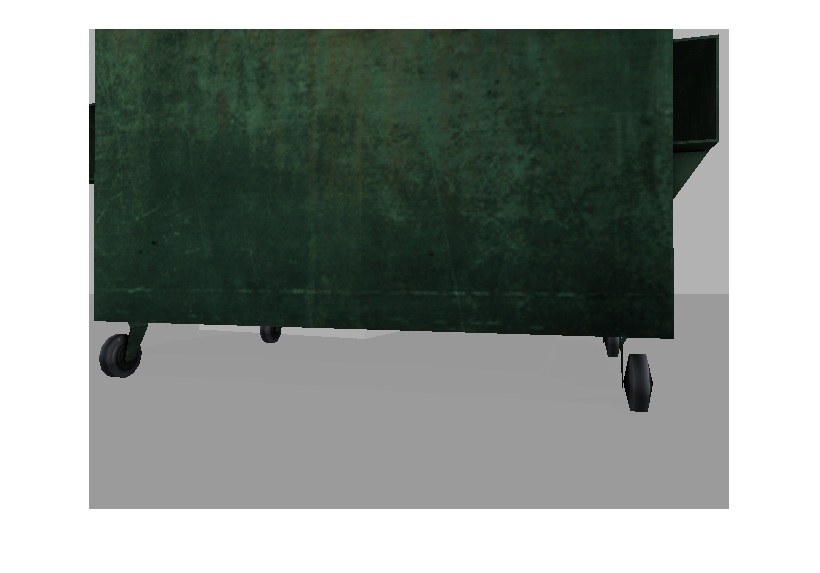

% Grap image from camera
if ismember('/camera/rgb/image_color/compressed',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_color/compressed');
end

if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

Opgave 2 - Calculate k variable:

Z = 2;
X = 0.15

X = 0.1500

x = 43

x = 43

k = 573

k = 573

Opgave 3 - Plot relationen mellem målte objecters længde i pixels og kamera højde. relater dette plot til perspektiv - 

Opgave 4 - Detekter objekter og farver

Funktion: 

I = rgb2gray(img);

Unrecognized function or variable 'img'.

bw = imbinarize(I);
imshow(bw)